# IAVSD23 - Optimizing rail maintenance

## Input data (lookup table) and interpolation

% set parameters
tonnage = "H_32t";
interpolation_method = 'spline';

% read lookup tables
[H_table_MB5,H_table_MB6, risk_MB5, risk_MB6] = read_input_data(tonnage);

% plot table
% plot_figure('H_table5_heatmap', H_table_MB5);
% plot_figure('H_table6_heatmap', H_table_MB6);

% interpolations of H_table
H_table_interpol = interpolation(H_table_MB5,interpolation_method);
H_table_interpol_MB6 = interpolation(H_table_MB6,interpolation_method);
% H_table_interpol_makima = interpolation(H_table_MB5,'makima');
% H_table_interpol_spline = interpolation(H_table_MB5,'spline');
% H_table_interpol_cubic = interpolation(H_table_MB5,'cubic');

% get maximal lifetimes
[max_lifetime_MB5] = get_max_lifetime(risk_MB5);
[max_lifetime_MB6] = get_max_lifetime(risk_MB6);

% visualize the interpolated H_tables
% plot_figure(strcat(interpolation_method,' interpolation'), H_table_interpol)
% plot_figure(strcat(interpolation_method,' interpolation'), H_table_interpol_MB6)

## LCC Simulation for different maintenance strategies

% average yearly gauge widening (in mm/year)
avg_yearly_gauge_widening = 0:0.1:2;

% find the optimals
opt_grinding = zeros(size(avg_yearly_gauge_widening));
opt_tamping = zeros(size(avg_yearly_gauge_widening));
opt_LCC = zeros(size(avg_yearly_gauge_widening));
opt_lifetime = zeros(size(avg_yearly_gauge_widening));
opt_grinding_MB6 = zeros(size(avg_yearly_gauge_widening));
opt_tamping_MB6 = zeros(size(avg_yearly_gauge_widening));
opt_LCC_MB6 = zeros(size(avg_yearly_gauge_widening));
opt_lifetime_MB6 = zeros(size(avg_yearly_gauge_widening));
for i=1:size(avg_yearly_gauge_widening,2)
    [opt_grinding(i),opt_tamping(i),opt_LCC(i),opt_lifetime(i)] = get_optimal(H_table_interpol, interpolation_method, "MB5", avg_yearly_gauge_widening(i), max_lifetime_MB5);
    [opt_grinding_MB6(i),opt_tamping_MB6(i),opt_LCC_MB6(i),opt_lifetime_MB6(i)] = get_optimal(H_table_interpol_MB6, interpolation_method, "MB6", avg_yearly_gauge_widening(i), max_lifetime_MB6);
end

## Plot simulation results

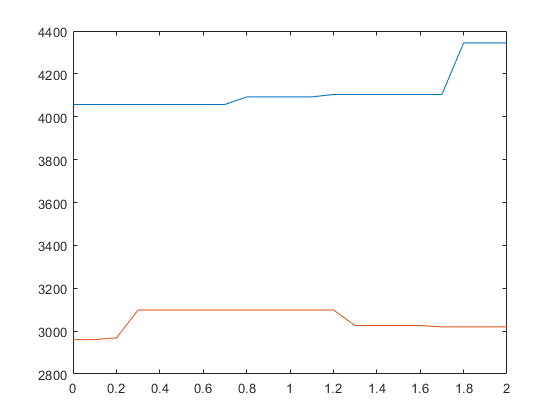

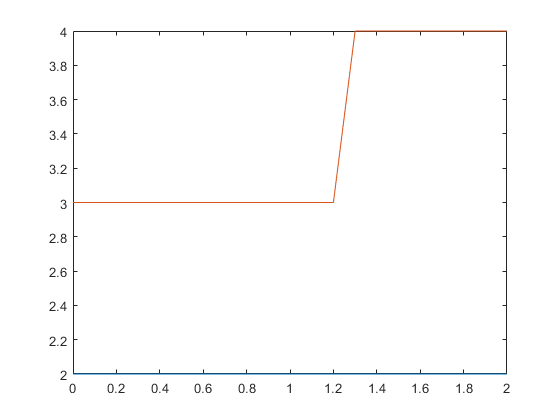

% arrange the data for the stapler plots
data_MB5 = [opt_tamping; opt_grinding];

data_MB6 = [opt_tamping_MB6; opt_grinding_MB6];

% plot the stapler plots
figure
subplot(1,2,1)
bar(avg_yearly_gauge_widening, data_MB5', 'stacked')
legend({'Optimal Tamping', 'Optimal Grinding'}, 'Location', 'bestoutside')
title('MB5')
xlabel('Average Yearly Gauge Widening (mm/year)')
ylabel('Optimal Number of Maintenance activities (#/year)')

subplot(1,2,2)
bar(avg_yearly_gauge_widening, data_MB6', 'stacked')
legend({'Optimal Tamping', 'Optimal Grinding'}, 'Location', 'bestoutside')
title('MB6')
xlabel('Average Yearly Gauge Widening (mm/year)')
ylabel('Optimal Number of Maintenance activities (#/year)')

% plot results
figure
yyaxis left
plot(avg_yearly_gauge_widening, opt_LCC, 'b-', 'LineWidth', 1.5);
hold on;
plot(avg_yearly_gauge_widening, opt_LCC_MB6, 'r-', 'LineWidth', 1.5);
ylabel('Minimal lifecycle costs (in SEK/m)', 'FontSize', 14);
yyaxis right
plot(avg_yearly_gauge_widening, opt_lifetime, 'b--', 'LineWidth', 1.5);
hold on;
plot(avg_yearly_gauge_widening, opt_lifetime_MB6, 'r--', 'LineWidth', 1.5);
ylabel('Optimal rail lifetime (in years)', 'FontSize', 14);
xlabel('Average gauge widening (mm/year)', 'FontSize', 14);
legend('MB5 LCC', 'MB6 LCC', 'MB5 lifetime', 'MB6 lifetime', 'Location', 'northwest');
set(gca, 'FontSize', 12) % set font size of tick labels
set(gca, 'FontName', 'Arial') % set font type of tick labels
set(get(gca, 'YLabel'), 'FontSize', 14) % set font size of y-axis label
set(get(gca, 'XLabel'), 'FontSize', 14) % set font size of x-axis label
set(get(gca, 'Title'), 'FontSize', 16) % set font size of plot title
set(findobj(gcf, 'type', 'legend'), 'FontSize', 12) % set font size of legend